# User-Defined Functions

So far, we have used scripts and built-in MATLAB functions to manipulate scalars, vectors, and matrices. We can also define our own [functions](https://www.mathworks.com/help/matlab/ref/function.html?searchHighlight=function&s_tid=srchtitle_function_1) that encode specific sets of tasks into function handles. Some benefits of defining functions include:

- Intermediate variables/calculations aren’t stored in the workspace--good to avoid cluttering if storing intermediate calculations not necessary

- Improve readability of code/scripts

## General Function Flow

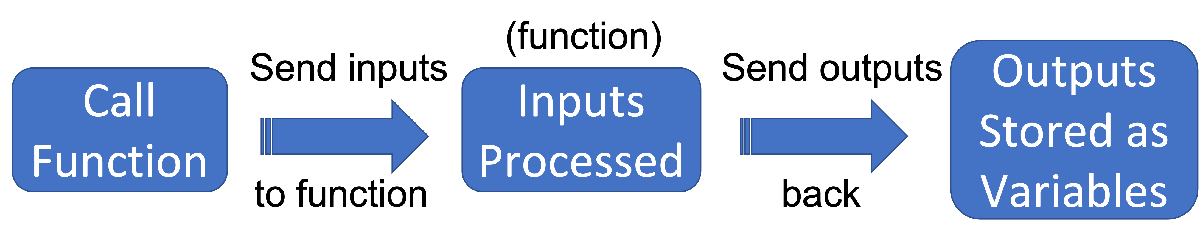

There are two primary ways to use functions. We can write [function files](https://www.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html) or define [local functions](https://www.mathworks.com/help/matlab/matlab_prog/local-functions.html) within a script. The general structure of the function doesn't change in either case, but the way we use/call the function does. 

Let's focus on writing a function file. To create a user-defined function file, click the arrow below “New” in the toolbar, then select “Function”. Note that the name of the file must match the name of the function.

## Anatomy of a Function

Functions, like script files, have a general structure/anatomy.

#### First line

The first line of a function file indicates you are in the function enviroment (i.e., creating a function--not a script). You will also name the function and define the function outputs and inputs in the first line of a function file.

function [outputArg1,outputArg2] = L04_Test_Function(inputArg1,inputArg2)

Based on this first line of the function, we can determine:

- Name: `Test_Function`

- Outputs: `outputArg1` and `outputArg2`

- Inputs: in`putArg1` and in`putArg1`

#### Function description

The next part of a function is the description of the function. Generally, there is a brief description of the function followed by a more detailed description of the function. Including this function description is important so that

- you remember how to use the functions you write, and

- other people can understand your functions.

#### Function body

This is where your function "does" what you want it to do. Here, we'll multiply the first function input by a constant and store it to the first function output, then divide the second function input by the same constant and store it to the second function output. It is best practice for the function output(s) to be the last line(s) of the function body.

We will define the constant as a so-called local variable inside the function file. **Local variables **are only stored within the function file itself.

constant = 10; % local constant defined within the function file
outputArg1 = inputArg1*constant; % multiply first input variable by constant, store to first output variable
outputArg2 = inputArg2/constant; % divide second input variable by constant, store to second output variable

#### Function end

The last line of any function simply ends the function.

end

## Calling Functions

The way we call a function depends on how we've defined it.

- We can call [function files](https://www.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html) from the Command Window or from inside a script. To do this, the function must be in current file path (i.e., folder).

- We can use [local functions](https://www.mathworks.com/help/matlab/matlab_prog/local-functions.html) within scripts. To do this, we write the function at the end of the script and can only call it within the script itself.

No matter how the function is defined, calling it will look the same. In general, we call a function--both ones we write and built-in MATLAB functions--by writing

`[y1,y2,...,yn] = functName(x1,x2,...,xm)`

Here, `y1,y2,...,yn` are the 1 through nth outputs of the function and `x1,x2,...,xm `are the 1 through mth inputs of the function. Note that it is not necessary that n = m. That is, the number of inputs to a function does not need to be equal to the number of outputs. To call our function `Test_Function` we might write

`[a,b] = Test_Function(3,5)`

Let's make sure we know exactly what happens when we write these lines. Let's imagine we called `Test_Function` from the Command Window with the line of code above.

- Call `Test_Function` from Command Window

- Send `3` and `5` to `Test_Function`

- Inside `Function_details`, set `inputArg1 = 3` and `inputArg2 = 5`

- Carry out code inside `Test_Function`, ultimately defining `outputArg1` and `outputArg2`

- Send outputs of `Test_Function `to Workspace

- Set  `a = outputArg1 `and `b = outputArg2` in Workspace

We could think of this visually as